**Part 2:** Produce 2D arrays of the specified function(s) via the specified method(s) and produce appropriate graph(s) *in another figure*.

Generate these functions:

- 
$$\exp \left(-x^2 -y^2 \right)$$


- $\mathrm{cos}\left(3\theta \right)\left(r-r^3 \right)\;\mathrm{exp}\left(-r^2 \right)$, where $\left(r,\theta \right)$are polar coordinates but plot in (x,y) space 

- HINT: you may use [atan2 (Links to an external site.)](https://au.mathworks.com/help/matlab/ref/atan2.html) or [angle. (Links to an external site.)](https://au.mathworks.com/help/matlab/ref/angle.html)

Demonstrate these methods at least once each:

- nested loops

- meshgrid *or* broadcasting

Show these plots once each:

- A top-down plot

- A 3D plot

Make sure that all plots are carefully presented to allow a full understanding of the results.

clc;
clear;

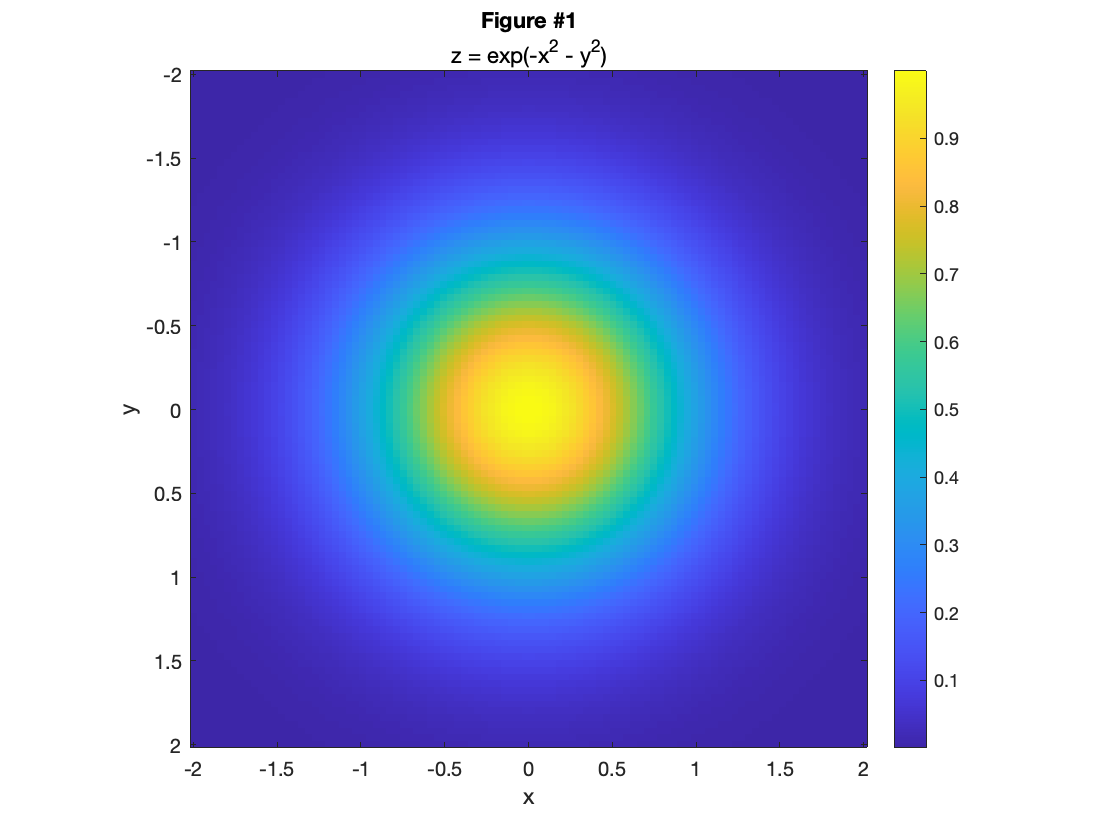

% Broadcasting and top-down plot
x = linspace(-2, 2);
y = linspace(-2, 2).';
z = exp(-x.^2 - y.^2); % broadcasting

imagesc(x, y, z);
colorbar
axis('image')
subtitle('z = exp(-x^2 - y^2)')
xlabel('x')
ylabel('y')
title('Figure #1')

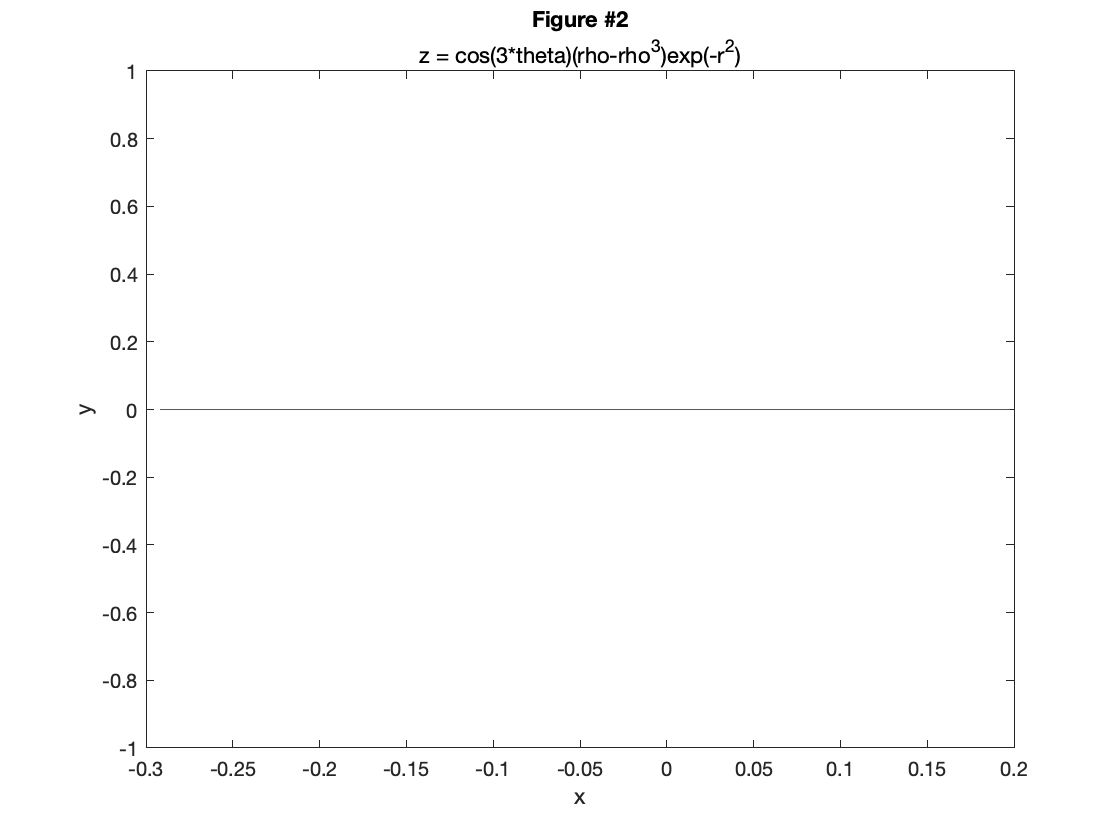

% Generate Polar Coordinates
rho = linspace(0, 10); % rho must be positive
theta = linspace(-pi, pi);

% Compute function (in terms of polar coodinates)
z = nan([length(rho), length(theta)]);
for i = 1:length(rho)
    for j = 1:length(theta)
        z(i, j) = cos(3.*theta(1, j)) .* (rho(1, i) - rho(1, i).^3) .* exp(-rho(1, i).^2);
    end
end

% Convert computed z coordinates (which is in polar) to cartesian
xCartArray = nan([1, length(z)]);
yCartArray = nan([1, length(z)]);

for i = 1:length(rho)
    for j = 1:length(theta)
        xCart = z(i, 1) .* cos(z(1, i));
        yCart = z(i, 1) .* sin(z(1, i));

        % Add computed cartesian coordinates to cartesian axis array
        xCartArray(1, length(xCartArray) + 1) = xCart;
        yCartArray(1, length(yCartArray) + 1) = yCart;
    end
end

% Plot cartesian coordinates
plot(xCartArray, yCartArray);
title('Figure #2')
subtitle('z = cos(3*theta)(rho-rho^3)exp(-r^2)');
xlabel('x');
ylabel('y');